clear all;
clc;
close all;

file_name = "bianco_3_sw";
bag = ros2bagreader("Test_ur/" + file_name)

bag =   ros2bagreader with properties:

           FilePath: '/Users/lucabeber/Documents/Dottorato/Cubes/Test_ur/bianco_3_sw/bianco_3_sw_0.db3'
          StartTime: 1701193309021195162
            EndTime: 1701193335971068308
    AvailableTopics: [1×3 table]
        MessageList: [13476×3 table]
        NumMessages: 13476



bag_data = select(bag,"Topic","/data_control");
mes_data = readMessages(bag_data);

n_mess = bag_data.NumMessages;


sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020

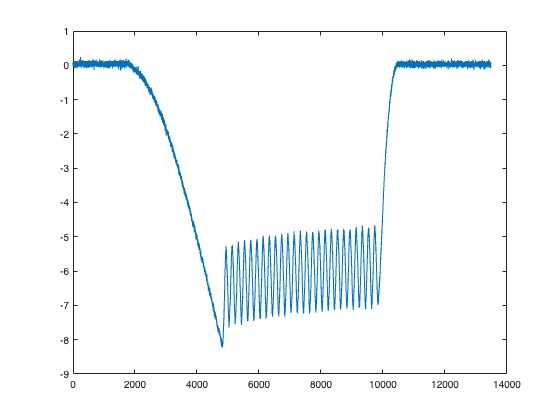


force_z = zeros(n_mess,1);
for i = 1:n_mess
    force_z(i) =  mes_data{i, 1}.data(6);  
end

plot(force_z)

force_z = -force_z

force_z =    -0.0771
    0.0189
   -0.0320
   -0.1005
   -0.0537
   -0.0085
   -0.0785
   -0.0543
   -0.0310
   -0.0538


td = 0:0.002:10

td =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


tmp = (force_z(4485)/14.0244 * exp(f.b*td) + force_z(4485)/1.0783*exp(f.d*td))

Unable to resolve the name 'f.b'.

plot(force_z(4485:end))
hold on
plot(tmp)
hold off

comp =force_z(4485:4485+5000) + (force_z(4485) - tmp)'

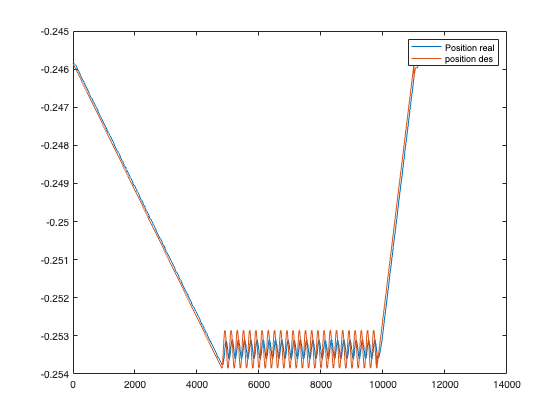


position_real = zeros(n_mess,1);
position_des = zeros(n_mess,1);
for i = 1:n_mess
    position_real(i) =  mes_data{i, 1}.data(3);  
    position_des(i) =  mes_data{i, 1}.data(2); 
end

plot([position_real,position_des])
legend(["Position real","position des"])

penetration = zeros(n_mess,1);
for i = 1:n_mess
    penetration(i) =  position_real(1)-position_real(i);
end

plot(sim_time(:),penetration(:))

velocity_z = zeros(n_mess,1);
for i = 1:n_mess
    velocity_z(i) =  mes_data{i, 1}.data(5);  
end

plot(smoothdata(velocity_z,"SmoothingFactor",0.2))
velocity_z = smoothdata(velocity_z,"SmoothingFactor",0.1)

plot(penetration,-force_z)

f = -smoothdata(force_z,"SmoothingFactor",0.01);
df = smooth(diff(f)/0.002);
ddf = smooth(diff(df)/0.002);

p = smooth(penetration);
dp = -velocity_z;
ddp = smooth(diff(dp)/0.002);

% force_zd = zeros(n_mess,1);
% force_zd(1:n_mess-1) = diff(smoothdata(force_z,"SmoothingFactor",0.3))/(dT);
% force_zd(n_mess)=force_zd(n_mess-1);
% plot(force_zd)

% Fit the model 'z = k * u + c * up'
X = [penetration,-velocity_z]
mdl = fitlm(X(4485:4485+5000,:), comp, "y~-1+x1+x2")

% Display the regression results
%disp(mdl);
ls_coeff = lsqr(X(4485:4485+5000,:), comp)

el = ls_coeff(1)/0.05


plot(sim_time(4485:4485+5000),  ls_coeff(1)*X(4485:4485+5000,1)  + ls_coeff(2)*X(4485:4485+5000,2))
hold on 
plot(sim_time(4485:4485+5000), comp)
hold off 
legend(["est","ft"])

% Fit the model 'z = k * u^n + c * up^n'
n = 1.5
X = real([(penetration).^(n),-velocity_z.*(penetration.^(n-1))]);
mdl = fitlm(X, -force_z, "y~-1+x1+x2")

% Display the regression results
%disp(mdl);
ls_coeff2 = lsqr(X(4485:4485+5000,:), comp)

% Get the coefficients 'a' and 'b' from the model
%stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
% damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
% mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'


plot(sim_time(4485:4485+5000),  ls_coeff2(1)*X(4485:4485+5000,1)  + ls_coeff2(2)*X(4485:4485+5000,2))
hold on 
plot(sim_time(4485:4485+5000), comp)
hold off 
legend(["est","ft"])



## Elasticity and viscosity

el = 3 * ls_coeff2(1) / (4 * sqrt(0.02)) %* ( 1 - 0.7^2)% Fit the model 'z = k * u^n + c * up^n'

n = 1.5

mdl = fitlm(X(1:4500,:), -force_z(1:4500), "y~-1+x1+x2")

% Display the regression results
%disp(mdl);
ls_coeff3 = lsqr(X(1:4500,:),-force_z(1:4500))

plot(sim_time,  ls_coeff3(1)*X(:,1)  + ls_coeff3(2)*X(:,2))
hold on 
plot(sim_time, -force_z)
hold off 
legend(["est","ft"])

n = 1.5
X = real([(penetration(1:3030)+0.00025).^(n),-velocity_z(1:3030).*((penetration(1:3030)+0.00025).^(n-1))]);
mdl = fitlm(X, -force_z(1:3030), "y~-1+x1")

% Display the regression results
%disp(mdl);
ls_coeff3 = lsqr(X,force_z(1:3030))

plot(sim_time(1:3030),  ls_coeff3(1)*X(:,1) + ls_coeff3(2)*X(:,2))
hold on 
plot(sim_time(1:3030), force_z(1:3030))
hold off 
legend(["est","ft"])